Problem 1:

%% generate the data
rng('default'); rng(12);
dt=0.01; t=(0:dt:1)'; sd=0.1;
x=1+0.5*t;                   % true signal, theta=[1;0.5]
y=x+sd*randn(size(x));       % generate the noisy data

% compute parameters of exact Gaussian posterior
m0=[0;0]; P0=eye(2);   % prior mean and covariance
H =[ones(size(t)) t]; R=sd^2*eye(length(t));
disp('Exact solution')

Exact solution


PT=inv(inv(P0) + H'/R*H)

PT =     0.0004   -0.0006
   -0.0006    0.0012


mT=PT*(H'*(R\y)+P0\m0)

mT =     0.9989
    0.5143


theta3 = log(sd.^2)

theta3 = -4.6052

RR = eye(length(t));

% Gradient-free optimisation
logmvnpdf=@(x,m,P) -0.5*(x-m)'/P*(x-m)-trace(log(chol(2*pi*P)));
phiT=@(th) -logmvnpdf(y,H*th(1:2),exp(th(3))*RR)-logmvnpdf(th(1:2),m0,P0);
theta_MAP=fminsearch(phiT,[0;0;0])

theta_MAP =     0.9989
    0.5143
   -4.6719


MAP_sigma = sqrt(exp(theta_MAP(3)))

MAP_sigma = 0.0967

%finds correct solution

% Metropolis algorithm
N=5000; 
Sigma=eye(3)*0.002;
Nburnin=500;
theta=zeros(3,N);
accept_count=0;
theta_prev=mvnrnd([m0;0],eye(3))';
phi_prev=phiT(theta_prev);
for i=1:N
    theta_prop=mvnrnd(theta_prev,Sigma)';
    phi_prop=phiT(theta_prev);
    alpha=min(1,exp(phi_prev-phi_prop));
    if alpha>=rand
        accept_count=accept_count+1;
        theta(:,i)=theta_prop;
        theta_prev=theta_prop;
        phi_prev=phi_prop;
    else
        theta(:,i)=theta_prev;
        %R_values(:,i) = R_prev;
    end
end
disp('Random-walk Metropolis')

Random-walk Metropolis


mMCMC=mean(theta(:,Nburnin:end),2)

mMCMC =     0.1606
   -0.5466
   -2.0989


sigma_MCMC = sqrt(exp(mMCMC(3)))

sigma_MCMC = 0.3501

Pmcmc=cov(theta(:,Nburnin:end)')

Pmcmc = 	1.0e+-5 *

    0.8603   -0.4121    0.3004
   -0.4121    0.1974   -0.1439
    0.3004   -0.1439    0.1049


accept_rate=accept_count/N

accept_rate = 6.0000e-04


%seems that this doesn't find solution so let's try adaptive one

figure(1)
subplot(221)
plot(1:N,theta,'.','markersize',1)
axis([0 N 0 1.5])

subplot(223)
plot(theta(1,:),theta(2,:),'.','markersize',1)
axis([.9 1.1 0.4 0.6]), axis square

% Robust Adaptive Metropolis algorithm
gamma=0.9; 
alpha_target=0.234;
theta=zeros(3,N);
accept_count=0;
theta_prev=mvnrnd([m0;0],eye(3))';
phi_prev=phiT(theta_prev);
S=chol(Sigma,'lower');
for i=1:N
    r=randn(size([m0;0]));
    theta_prop=theta_prev+S*r;
    phi_prop=phiT(theta_prop);
    alpha=min(1,exp(phi_prev-phi_prop));
    if alpha>=rand
        accept_count=accept_count+1;
        theta(:,i)=theta_prop;
        theta_prev=theta_prop;
        phi_prev=phi_prop;
    else
        theta(:,i)=theta_prev;
    end
    if i>Nburnin
        eta=1/(i-Nburnin)^gamma;
        u=r/norm(r);
        SS=S*(eye(size(S))+eta*(alpha-alpha_target)*(u*u'))*S';
        S=chol(SS,'lower');
    end
end

%this converges to correct solution, the Sigma for theta 1 and 2 are
%significantly smaller than Sigma for theta 3(when looking at diagonal
%values of Pmcmc)

disp('Robust Adaptive Random-walk Metropolis')

Robust Adaptive Random-walk Metropolis


mMCMC=mean(theta(:,Nburnin:end),2)

mMCMC =     1.0009
    0.5113
   -4.6042


sigma_MCMC = sqrt(exp(mMCMC(3)))

sigma_MCMC = 0.1000

Pmcmc=cov(theta(:,Nburnin:end)')

Pmcmc =     0.0004   -0.0006    0.0002
   -0.0006    0.0011   -0.0006
    0.0002   -0.0006    0.0266


accept_rate=accept_count/N

accept_rate = 0.2512

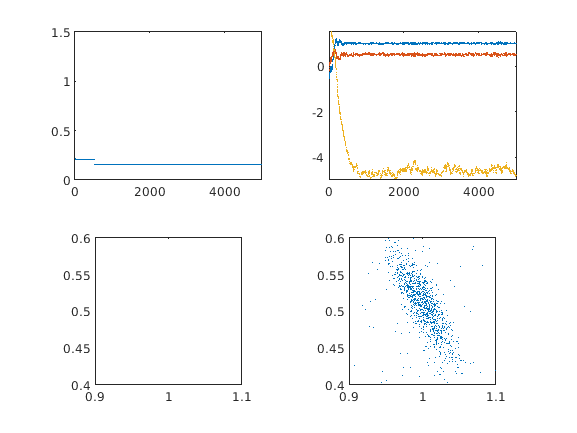

subplot(222)
plot(1:N,theta,'.','markersize',1)
axis([0 N -5 1.5])
subplot(224)
plot(theta(1,:),theta(2,:),'.','markersize',1)
axis([.9 1.1 0.4 0.6]), axis square

Problem 2:

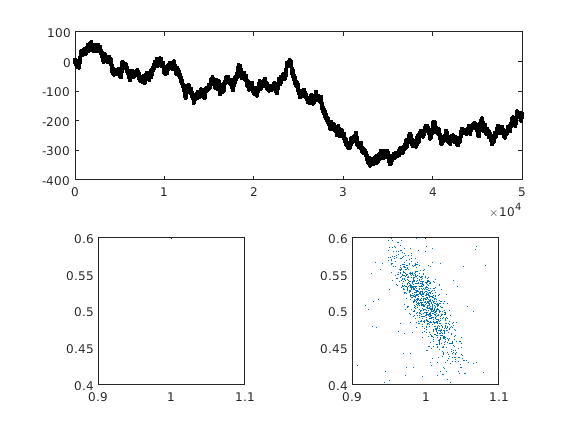

nk_values = [100,1000,10000,50000];
R_vars = zeros(1,length(nk_values));
for nk_index = 1:length(nk_values)
    nk_index;
    nk = nk_values(nk_index);
    [R_mean,R_var] = example12_1(nk);
    R_vars(nk_index) = R_var;
end

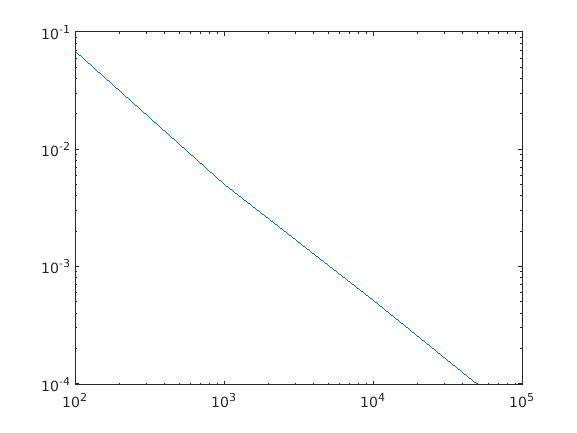


figure
loglog(nk_values,R_vars)

standard_deviation = sqrt(R_vars(end))

standard_deviation = 0.0099


%as we can see from figure that variance of R is inversely proportional to
%number of observations. We need 50000 observations for 0.01 standard
%deviation.

Problem 3:

% generate the example12_1 data
rng('default'); rng(0);
nk=1000;
x0=0; Q=1; R=1;
X=zeros(1,nk);Y=zeros(1,nk);
x=x0;
for k=1:nk
    x=x+sqrt(Q)*randn; X(k)=x;
    Y(k)=x+sqrt(R)*randn;
end

phiT=@(theta) phi_prob3(theta,Y);
R_MAP=fminsearch(phiT,[0.01;0.01])   % incorrect initial guess

R_MAP =     1.0459
    0.9523


R_MAP1=fminunc(phiT,[0.9;0.9])


Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


R_MAP1 =     1.0459
    0.9523


Problem 4:

% generate the example12_1 data
rng('default'); rng(0);
nk=1000;
x0=0; Q=1; R=1;
X=zeros(1,nk);Y=zeros(1,nk);
x=x0;
for k=1:nk
    x=x+sqrt(Q)*randn; X(k)=x;
    Y(k)=x+sqrt(R)*randn;
end

phiT=@(theta) phi_prob4(theta,Y);
options=optimoptions(@fmincon,'GradObj','on');
x00=[0.1;0.9]; %initial quess
lb=[0;0]; A=[]; b=[]; Aeq=[]; beq=[]; ub=[];
R_MAP = fmincon(phiT,x00,A,b,Aeq,beq,lb,ub,[],options)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


R_MAP =     0.9877
    1.0007


%this gives a bit better result with gradient

Problem 5:

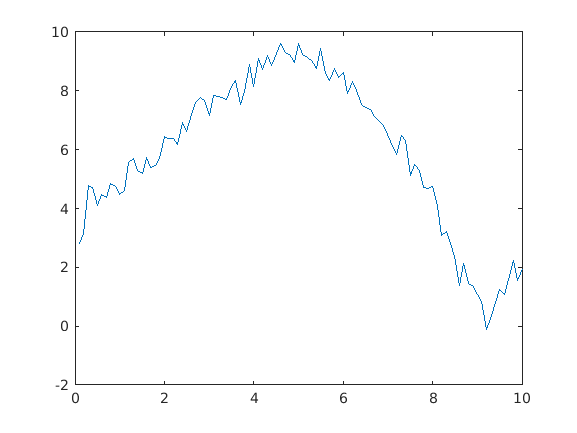

rng('default'); rng(0);
DT=0.1; nk=100; Qc=1; r=0.1; x0=[4;0];
T=(1:nk)*DT; X=zeros(1,nk); Y=zeros(1,nk);
Ak=[1,DT;0,1]; Qk=Qc*[DT^3/3,DT^2/2;DT^2/2,DT];
x=x0;
for k=1:nk
    x=mvnrnd(Ak*x,Qk)'; X(k)=x(1);
    Y(k)=norm([0.5-x(1);0.1])+sqrt(r)*randn;
end

plot(T,Y)

%produces weird results, no idea why. Maybe bug somewhere
phiT5=@(theta) phi_prob5(theta,Y);
MAP=fminsearch(phiT5,[0.5;0.1])

MAP =    -1.2239
    2.8014


MAP1=fminunc(phiT5,[0.5;0.1])


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


MAP1 =    -1.4273
    2.1363


MAP2 = fmincon(phiT5,[0.5;0.1])


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


MAP2 =    -0.6619
    4.2606


Functions

function [R_mean,R_var] = example12_1(nk_number)
% example 12.1, estimation of noise covariance for Gaussian random walk

%% generate the data
rng('default'); rng(0);
nk=nk_number;
x0=0; Q=1; R=1;
X=zeros(1,nk);Y=zeros(1,nk);
x=x0;
for k=1:nk
    x=x+sqrt(Q)*randn; X(k)=x;
    Y(k)=x+sqrt(R)*randn;
end
figure(1)
subplot(211)
plot(0:nk,[x0,X],'r-',1:nk,Y,'k.')
phiT=@(theta) phi(theta,Y);

%% Maximum A-posteriori (MAP) estimate using optimisation
%R_MAP=fminsearch(phiT,0.5);   % incorrect initial guess
%R_MAP1=fminunc(phiT,0.5);
%R_MAP2=fminbnd(phiT,0.1,10);

%% Robust Adaptive Metropolis algorithm
N=1000;                              % number of samples
Nburnin=100;                         % how many initial samples to discard
theta_prev=1;                        % initialise the sample path
Sigma=0.5*eye(length(theta_prev));   % variance of Metropolis step
gamma=0.75; alpha_target=0.234;      % RAM adaptation parameters
accept_count=0;                      % initialise the counter
theta=zeros(length(theta_prev),N);   % preallocation
phi_prev=phiT(theta_prev);
S=chol(Sigma,'lower');
for i=1:N
    r=randn(size(x0));
    theta_prop=theta_prev+S*r;       % proposed sample
    phi_prop=phiT(theta_prop);
    alpha=min(1,exp(phi_prev-phi_prop));
    if alpha>=rand                   % accept proposal
        accept_count=accept_count+1;
        theta(:,i)=theta_prop;
        theta_prev=theta_prop;
        phi_prev=phi_prop;
    else
        theta(:,i)=theta_prev;
    end
    if i>Nburnin                    % adjust the step covariance
        eta=1/(i-Nburnin)^gamma;
        u=r/norm(r);
        SS=S*(eye(size(S))+eta*(alpha-alpha_target)*(u*u'))*S';
        S=chol(SS,'lower');
    end
end
mMCMC=mean(theta(:,Nburnin:end),2);
Pmcmc=cov(theta(:,Nburnin:end)');
accept_rate=accept_count/N;
R_mean = mMCMC;
R_var = Pmcmc;
end

function val=phi(theta,Y)
if theta<=0, val=inf; return, end  % because R must be positive
A=1; Q=1; H=1; R=theta; m=0; P=0;
val=0;  % flat prior; any constant will do
for k=1:size(Y,2)
    m=A*m; P=A*P*A'+Q;  % KF prediction
    v=Y(:,k)-H*m; S=H*P*H'+R;
    val=val+0.5*v'/S*v+sum(log(diag(chol(2*pi*S))));
    K=P*H'/S; m=m+K*v; P=P-K*S*K';  % KF update
end
end

Problem 3 function

function val=phi_prob3(theta,Y)
if theta(1)<=0, val=inf; return, end  % because R must be positive
A=1; Q=theta(1); H=1; R=theta(2); m=0; P=0;
val=0;  % flat prior; any constant will do
for k=1:size(Y,2)
    m=A*m; P=A*P*A'+Q;  % KF prediction
    v=Y(:,k)-H*m; S=H*P*H'+R;
    val=val+0.5*v'/S*v+sum(log(diag(chol(2*pi*S))));
    K=P*H'/S; m=m+K*v; P=P-K*S*K';  % KF update
end
end

Problem 4 function

function [val,grad_val]=phi_prob4(theta,Y)
if theta(1)<=0, val=inf; return, end  % because R must be positive
A=1; Q=theta(1); H=1; R=theta(2); m=0; P=0;
val=0;  % flat prior; any constant will do
grad_val = [0;0]; %gradient
for k=1:size(Y,2)
    m=A*m; P=A*P*A'+Q;  % KF prediction
    v=Y(:,k)-H*m; S=H*P*H'+R;
    val=val+0.5*v'/S*v+sum(log(diag(chol(2*pi*S))));
    %This gradient works only with one-dimensional values.
    grad_val = grad_val + [-0.5*v*v'*H*H'/(S^2)+0.5*H*H'/S;-0.5*v*v'/(S^2) + 0.5/S];
    K=P*H'/S; m=m+K*v; P=P-K*S*K';  % KF update
end
end

Problem 5 functions

function [val]=phi_prob5(theta,Y)
m=[4;0]; P=0.01*eye(2);
r = 0.1;
DT=0.1;
Qc = 1;
Qk=Qc*[DT^3/3,DT^2/2;DT^2/2,DT];
val=0;  % flat prior; any constant will do
for k=1:size(Y,2)
    [mu,S]=gf_predict(m,P,@tracking_f,Qk,@GaussApproxEKF,theta);
    v=Y(:,k)-mu; 
    val=val+0.5*v'/S*v+sum(log(diag(chol(2*pi*S))));
    [m,P]=gf_update(mu,S,Y(k),@tracking_h,r,@GaussApproxEKF,theta);
end
end

function [m,P]=gf_update(m,P,y,h,R,GaussApprox,theta)
if ~isnan(y)
    [mu,S,C]=GaussApprox(m,P,h,R,theta);
    K=C/S;
    P=P-K*S*K';
    m=m+K*(y-mu);
end
end

function [m,P]=gf_predict(m,P,f,Q,GaussApprox,theta)
[m,P]=GaussApprox(m,P,f,Q,theta);
end

function [mu,S,C]=GaussApproxEKF(m,P,g,E,theta)
[mu,Gx]=g(m,theta);
C=P*Gx';
S=Gx*C+E;
end

function [fval,Fx,Fxx]=tracking_f(x,theta)
DT = 0.1;
Fx = [1 DT; 0 1];
fval = Fx*x;
Fxx{1} = zeros(2,2);
Fxx{2} = zeros(2,2);
end

function [hval,Hx,Hxx]=tracking_h(x,theta)
hval = norm([theta(1)-x(1);theta(2)]);   
Hx = [(x(1)-theta(1))/hval 0];
Hxx{1} = [0.01/hval^3 0; 0 0];
end